% Record videostraem using webcam fro 30 sec. 
clc
clear all
close all hidden
webcamlist

ans = 1×1 cell array
    {'/dev/video0'}


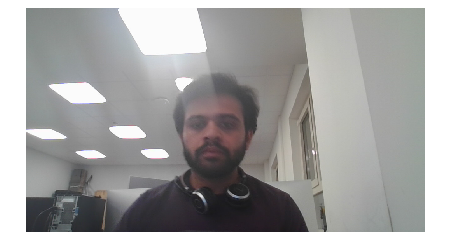


% Create a webcam object
cam = webcam;

% Set the video resolution (optional)
% You can get a list of supported resolutions using cam.AvailableResolutions
cam.Resolution = '1280x720';

% Set up the video writer
outputVideo = VideoWriter('outputVideo.avi', 'Uncompressed AVI');
outputVideo.FrameRate = 30; % Set the frame rate (frames per second)
open(outputVideo);

% Capture and record video for a certain duration
durationInSeconds = 10;
tic; % Start timer
while toc < durationInSeconds
    % Capture a frame from the webcam
    frame = snapshot(cam);

    % Display the frame (optional)
    imshow(frame);

    % Write the frame to the video file
    writeVideo(outputVideo, frame);
end


% Close the video writer
close(outputVideo);

% Clear the webcam object
clear cam;

% Optical Flow using FarneBack method: display flow vector
vidReader = VideoReader('outputVideo.avi');

opticFlow = opticalFlowFarneback

opticFlow =   opticalFlowFarneback with properties:

    NumPyramidLevels: 3
        PyramidScale: 0.5000
       NumIterations: 3
    NeighborhoodSize: 5
          FilterSize: 15


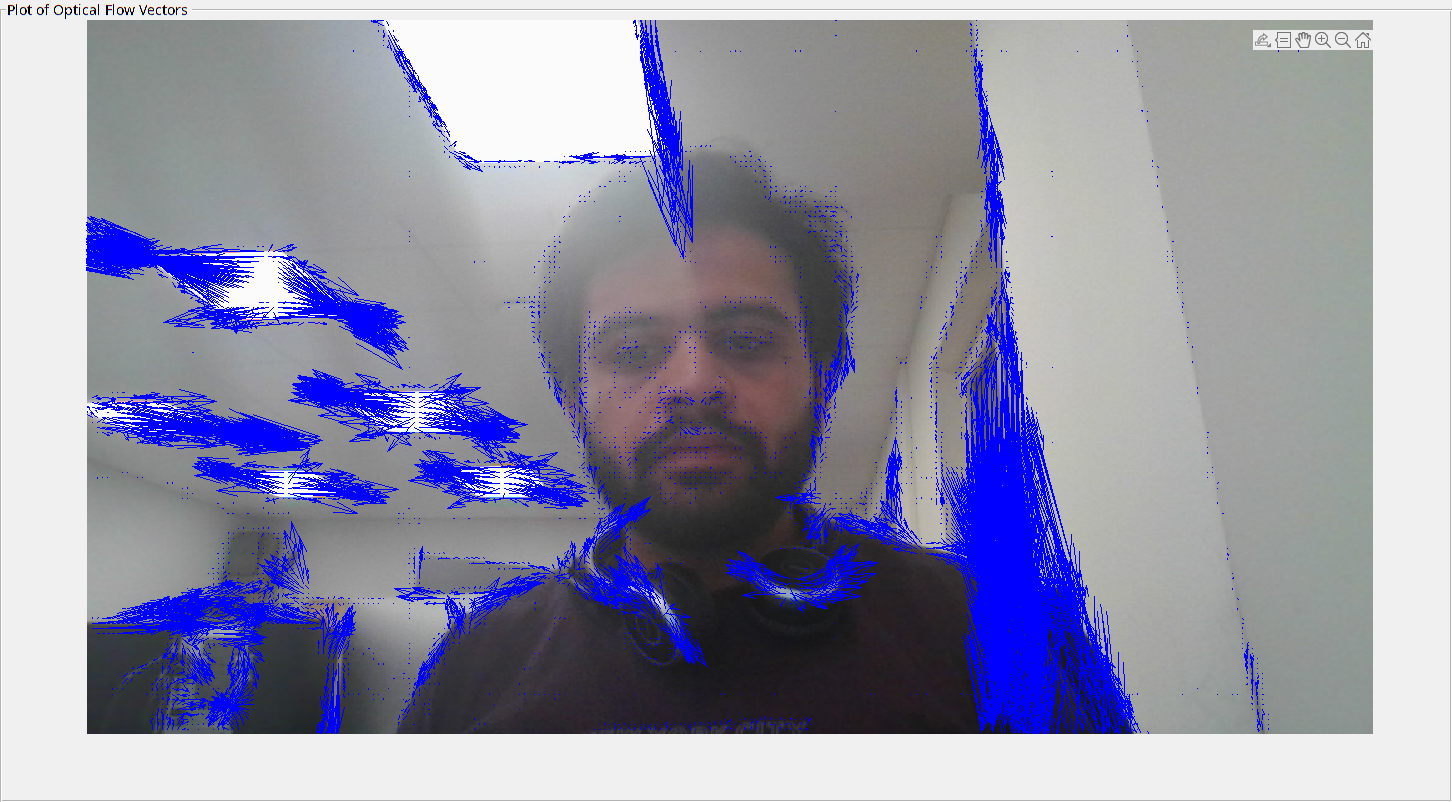

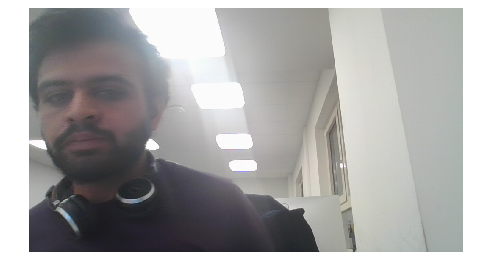

Error using opticalFlow>parsePlotInputs
The value of 'Parent' is invalid. Input must be a valid axes handle.

Error in opticalFlow/plot (line 135)
            [h, inputs] = parsePlotInputs(varargin{:});


h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = im2gray(frameRGB);  
    flow = estimateFlow(opticFlow,frameGray);
    
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',2.0,'Parent',hPlot);
    hold off
    pause(10^-3)
end

% Optical Flow usinf FarneBack method method: display HSV flow field 
clc
clear all
close all hidden

vidReader = VideoReader('outputVideo.avi');

opticFlow = opticalFlowFarneback

opticFlow =   opticalFlowFarneback with properties:

    NumPyramidLevels: 3
        PyramidScale: 0.5000
       NumIterations: 3
    NeighborhoodSize: 5
          FilterSize: 15


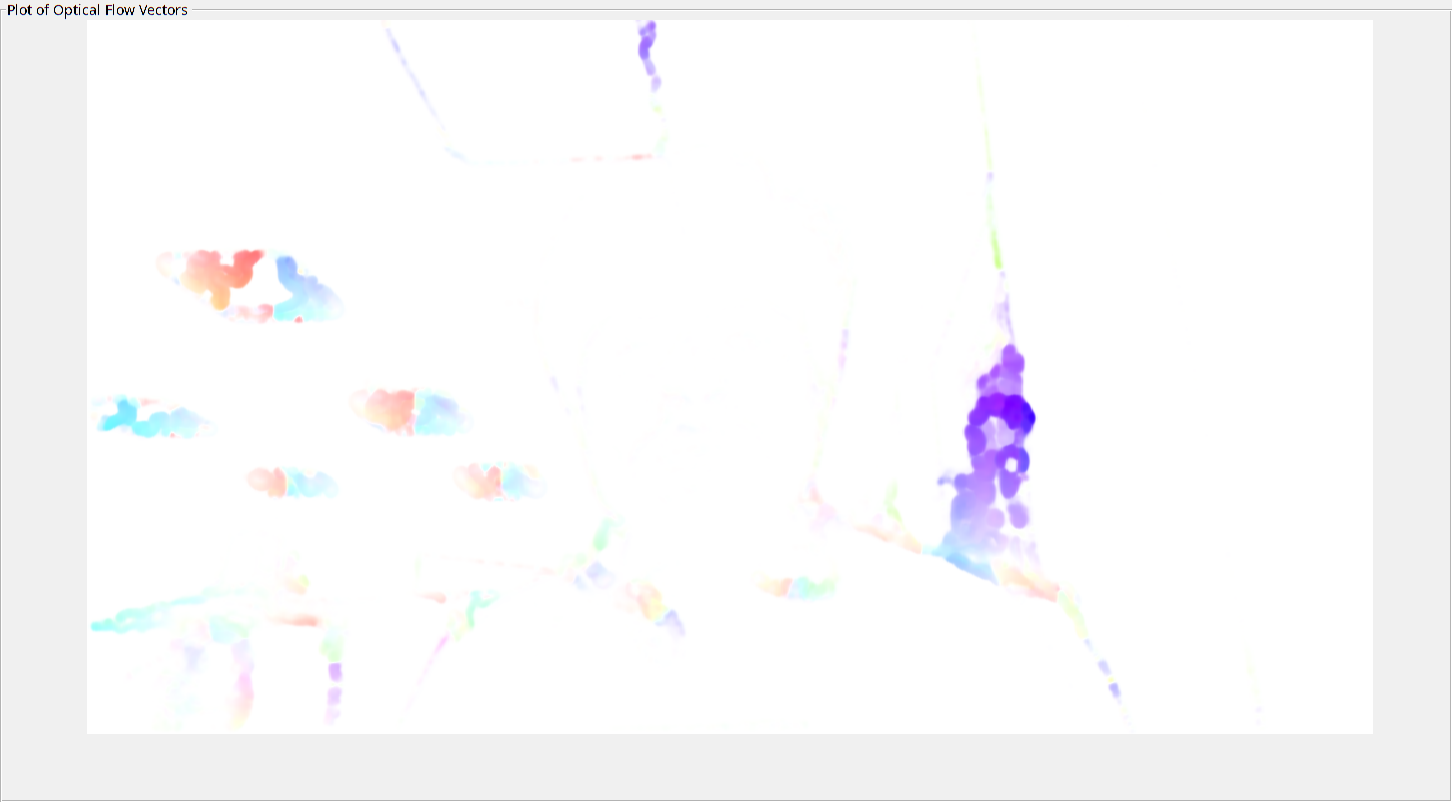

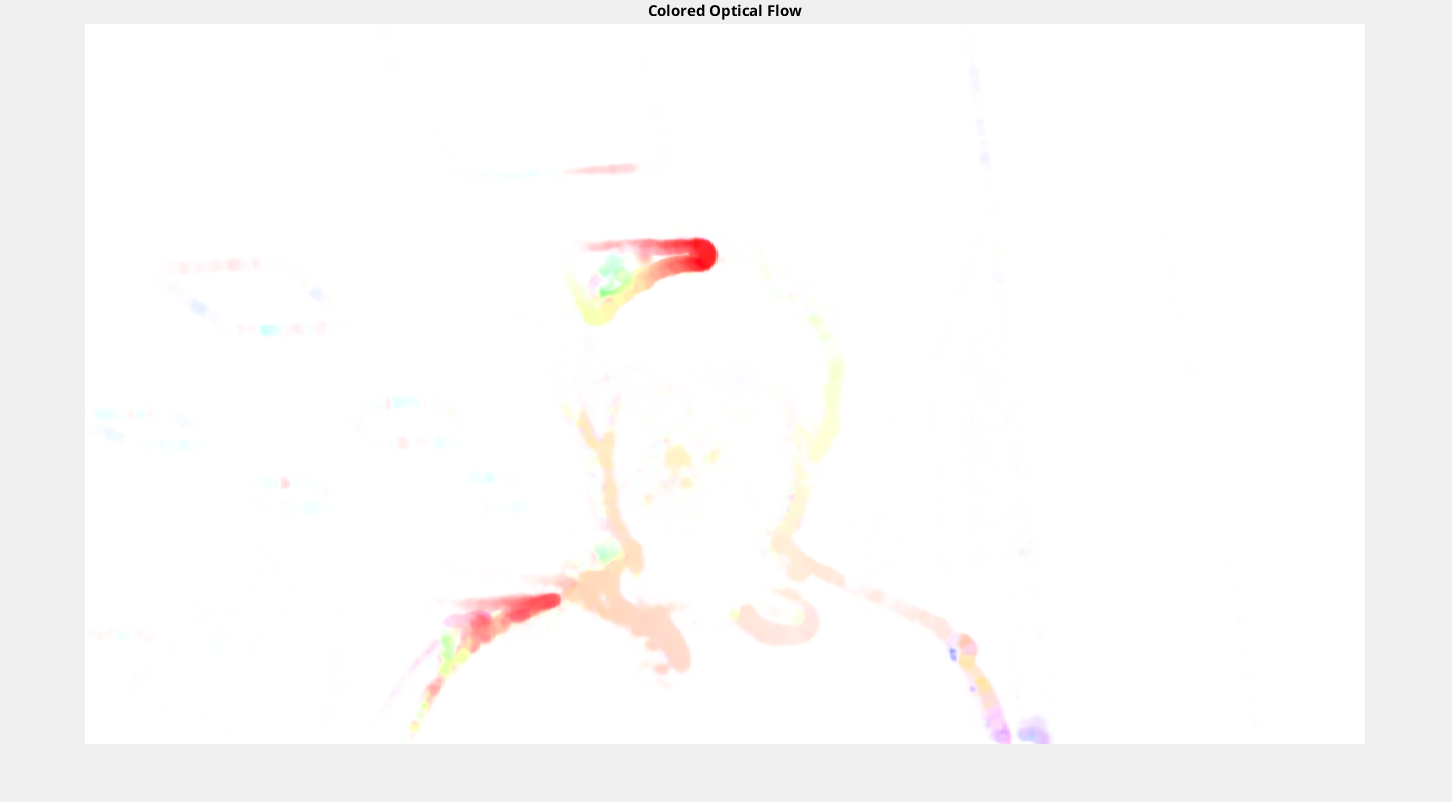


h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

while hasFrame(vidReader)
    frameRGB = readFrame(vidReader);
    frameGray = im2gray(frameRGB);  
    flow = estimateFlow(opticFlow,frameGray);
    
    magnitude = sqrt(flow.Vx.^2 + flow.Vy.^2);
    direction = atan2d(flow.Vy, flow.Vx);

    coloredFlow = flowToColor(magnitude, direction);

    imshow(coloredFlow);
    title('Colored Optical Flow');

    pause(10^-3)

end

function coloredFlow = flowToColor(magnitude, direction)
    % Normalize magnitude for better visualization
    normalizedMagnitude = magnitude / max(magnitude(:));

    % Convert direction to RGB colors using the hsv2rgb function
    coloredFlow = hsv2rgb(cat(3, (direction + 180) / 360, normalizedMagnitude, ones(size(magnitude))));
end